# Optimización con restricciones usando `fmincon `en MATLAB 

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x(1) - 2)^2 + (x(2) - 2)^2;

% Definir la restricción de igualdad
nonlcon = @(x) deal([], x(1) + x(2) - 2);

% Punto inicial para el solver
x0 = [0, 0];  % Valor inicial para las variables x e y

% Usar fmincon para encontrar el mínimo con restricción
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
[x_opt, fval] = fmincon(f, x0, [], [], [], [], [], [], nonlcon, options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.000000e+00     2.000e+00     1.000e+00     0.000e+00     4.000e+00  
    1           6    2.000000e+00     4.441e-16     1.000e+00     1.414e+00     1.000e+00  
    2           9    2.000000e+00     2.220e-16     1.000e+00     3.140e-16     2.980e-08  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 


% Mostrar los resultados
disp('Punto óptimo:');

Punto óptimo:


disp(x_opt);

    1.0000    1.0000



disp('Valor de la función en el punto óptimo:');

Valor de la función en el punto óptimo:


disp(fval);

    2.0000



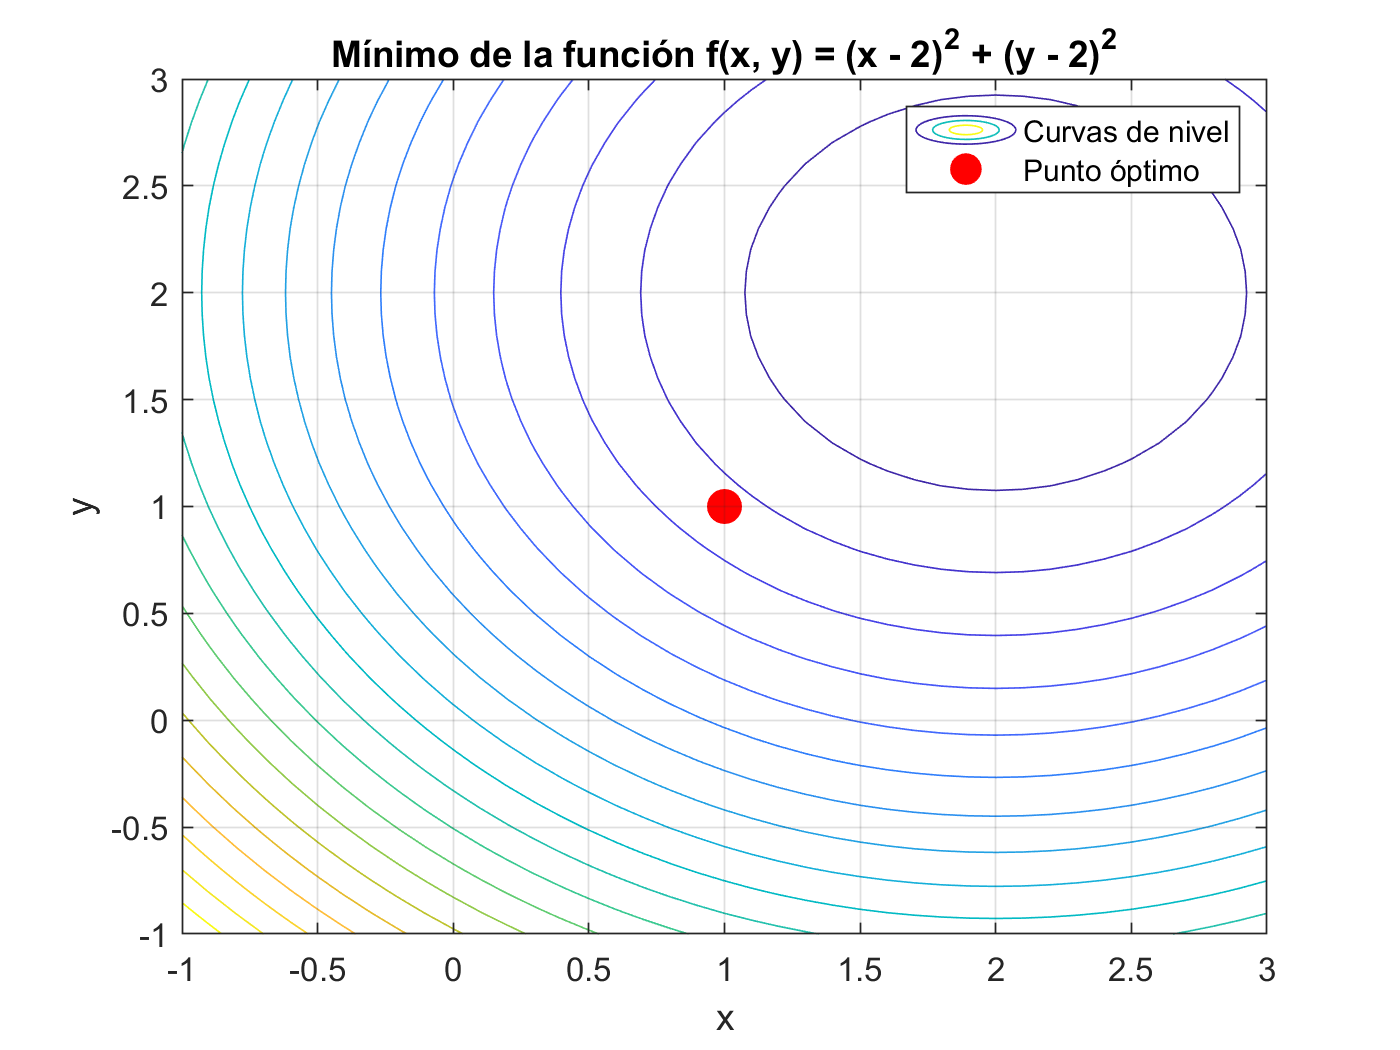


% Graficar la función objetivo y el punto óptimo
[X, Y] = meshgrid(-1:0.1:3, -1:0.1:3);
Z = (X - 2).^2 + (Y - 2).^2;

figure;
contour(X, Y, Z, 20);
hold on;
plot(x_opt(1), x_opt(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  % Punto óptimo
xlabel('x');
ylabel('y');
title('Mínimo de la función f(x, y) = (x - 2)^2 + (y - 2)^2');
legend('Curvas de nivel', 'Punto óptimo');
grid on;
hold off;